%%  Import predictions with different resolution
load('./input_data/NOVAmanualoutput2015.mat')
load('./input_data/FNDDS20152016.mat')
load('./input_data/FNDDS201520165foldsSMOTE.mat')
% for plots
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultAxesFontSize',15)

% unique to get the codes (all the foods manually classified by NOVA)
selt=NOVAmanualoutput2015(:, {'dr12ifdcd', 'FNDDS_food_description', 'FC_nova_group', 'fc_or_sr'});
selt.FC_nova_group(isnan(selt.FC_nova_group))=0;
dbwithlabels=unique(selt, 'stable');
% check if everything is in the same order (ok!)
disp('Check Order')

Check Order


disp(sum(dbwithlabels.dr12ifdcd==FNDDS20152016.Foodcode))

        8690



disp(sum(dbwithlabels.dr12ifdcd==FNDDS201520165foldsSMOTE.Foodcode))

        8690



disp('Statistics on NOVA classification')

Statistics on NOVA classification


disp('Number of foods with f labels')

Number of foods with f labels


disp(sum(dbwithlabels.fc_or_sr=='f'))

        2778




disp('Number of foods with s labels')

Number of foods with s labels


disp(sum(dbwithlabels.fc_or_sr=='s'))

        5308




disp('Number of foods not classified')

Number of foods not classified


disp(sum(dbwithlabels.fc_or_sr=='.'))

   604




disp('% Foods without a unique label')

% Foods without a unique label


disp(sum(~(dbwithlabels.fc_or_sr=='f'))/height(dbwithlabels))

    0.6803





disp("Of those classified as 'f' ...what is % NOVA classes")

Of those classified as 'f' ...what is % NOVA classes


dbwithlabels_f=dbwithlabels(dbwithlabels.fc_or_sr=='f',:);

disp('NOVA 1')

NOVA 1


nc=1;
disp(sum(dbwithlabels_f.FC_nova_group==nc))

   235



disp('%')

%


disp(sum(dbwithlabels_f.FC_nova_group==nc)/height(dbwithlabels_f)*100)

    8.4593




disp('NOVA 2')

NOVA 2


nc=2;
disp(sum(dbwithlabels_f.FC_nova_group==nc))

    50



disp('%')

%


disp(sum(dbwithlabels_f.FC_nova_group==nc)/height(dbwithlabels_f)*100)

    1.7999




disp('NOVA 3')

NOVA 3


nc=3;
disp(sum(dbwithlabels_f.FC_nova_group==nc))

   369



disp('%')

%


disp(sum(dbwithlabels_f.FC_nova_group==nc)/height(dbwithlabels_f)*100)

   13.2829




disp('NOVA 4')

NOVA 4


nc=4;
disp(sum(dbwithlabels_f.FC_nova_group==nc))

        2124



disp('%')

%


disp(sum(dbwithlabels_f.FC_nova_group==nc)/height(dbwithlabels_f)*100)

   76.4579



% choose the db
dbtableall=FNDDS201520165foldsSMOTE;
minensemble=false;

if minensemble
    col2sel={'Foodcode', 'Mainfooddescription'};
    dbtable=dbtableall(:, col2sel);
    dbtable.class=dbtableall.min_class;
    dbtable.p1=dbtableall.p1_minFPS;
    dbtable.p2=dbtableall.p2_minFPS;
    dbtable.p3=dbtableall.p3_minFPS;
    dbtable.p4=dbtableall.p4_minFPS;
    dbtable.FPS=dbtableall.min_FPS;
else  
    col2sel={'Foodcode', 'Mainfooddescription','class','p1','p2', 'p3','p4', 'FPS'};
    dbtable=dbtableall(:, col2sel);
end

db=dbtable{:, {'p1','p2', 'p3','p4'}};

%% processing score trained in 2009/2010 stratified by manual classification in 2015/2016
% full histograms
keySet={0,12,1,2,3,4};
valueSet={[102, 102, 102]/255,...
    [102, 102, 102]/255,...
    [0.4, 0.7607843137254902, 0.6470588235294118],...
    [0.9882352941176471, 0.5529411764705883, 0.3843137254901961],...
    [0.5529411764705883, 0.6274509803921569, 0.796078431372549],...
    [0.9058823529411765, 0.5411764705882353, 0.7647058823529411]};
colormapNOVA=containers.Map(keySet, valueSet);

% NOVA colors (originals)
classesNOVA=dbwithlabels.FC_nova_group;
cNOVA=zeros(size(db,1),3);
for ind=1:size(db,1)
    cNOVA(ind,:)=colormapNOVA(classesNOVA(ind));

end


hcell=cell(4,1);
figure, 
for ind=3:length(keySet)
    filter=(classesNOVA==keySet{ind});
    disp('Class')
    disp(keySet{ind})
    disp('Num elements')
    disp(sum(filter))
    
    hcell{ind-2}=histogram(dbtable.FPS(filter));
    hold on
    hcell{ind-2}.EdgeColor=colormapNOVA(keySet{ind});
    hcell{ind-2}.FaceColor=colormapNOVA(keySet{ind});
    
    
    if (hcell{ind-2}.NumBins/sqrt(sum(filter)))<0.5
        hcell{ind-2}.NumBins=round(sqrt(sum(filter)));
    end
    
    
end

Class


     1



Num elements


   342



Class


     2



Num elements


    51



Class


     3



Num elements


   437



Class


     4



Num elements


        2144



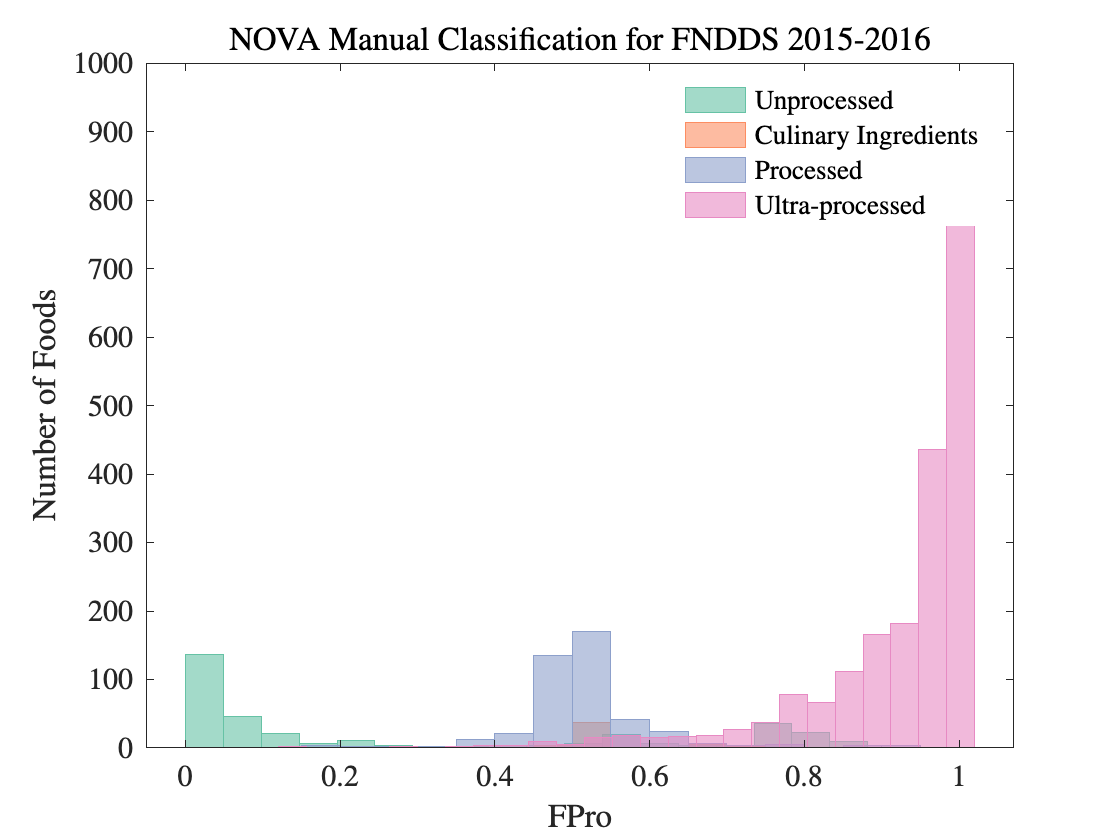


hcell{4}.NumBins=25;

xlabel('FPro')
ylabel('Number of Foods')
ll=legend('Unprocessed','Culinary Ingredients', 'Processed', 'Ultra-processed');
ll.EdgeColor='none';
title('NOVA Manual Classification for FNDDS 2015-2016')